% clear;

Read in AC Load (from Menzies Building)

% data = readtable("data.xlsx");
% %Remove the redundant data
% data = removevars(data, ["meter_serial", "meter_desc", "expwh","difference_exp_kwh","interval_start", "waste", "meter_id", "tariff_id", "impwh","stot", "pftot","md","qtot","difference_imp_kwh","epoch_timestamp","season_class_id","season_profile_id","day","week_number"]);

Read in DC load (From Mendeley Data)

% DCData = readtable("OnlineData\Commercial-Middle School.csv");
% 
% % Need to wrap days so that it starts on the same day of the week as the AC
% % load.
% numElementsToWrap = 8760-(24*7 + 24*7*30);
% numTotalElements = size(DCData(:,1));
% % Shift the middle portion to the beginning and wrap it
% startIndex = numTotalElements - numElementsToWrap + 1;
% DCDataWrapped = vertcat(DCData(startIndex:end,"Power_kW_"), DCData(1:startIndex - 1,"Power_kW_"));

Concatanate the data so there is one data set. 

% data = horzcat(data,DCDataWrapped);
% data = renamevars(data, "Power_kW_","DC"); %Rename the DC electrical load to DC
% data = renamevars(data, "ptot","AC");      %Rename the AC electrical load to AC

Clean up the Data

% %Fill data with no information. The previous value is used.
% [data,missingIndices] = fillmissing(data,"previous");
% %fill the anomalies caused by loadshedding. Lower 4.75 percentile of data
% %is replaced by linear interpolation.
% [data,outlierIndices5,thresholdLow5,thresholdHigh5] = filloutliers(data,...
%     "linear","percentiles",[4.75 100],"DataVariables","AC");

**Add some rows with indicator variables to help point towards patterns.**

**Will need to play with this to see what gives the best results!**

% %Add a column with the day of the week (mon-1 & sun-7)
% data.day = day(data.date, "iso-dayofweek");
% 
% %Conditions for day hours. 
% low_time = 0.29; %7am
% up_time = 0.75;  %6pm
% %Logical arrays for adding conditions.
% weekDayCondition = (data.day ~= 6) & (data.day ~= 7) ;
% SatCondition     = (data.day == 6);
% SunCondition     = (data.day == 7);
% wrkHrsCondition  = (data.time >= low_time) & (data.time <= up_time) & (data.day ~= 6) & (data.day ~= 7);
% dayTimeCondition = (data.time >= low_time) & (data.time <= up_time);
% 
% %Adding indicators to the table
% data.weekDay    = double(weekDayCondition);
% data.weekendDay = double(~weekDayCondition);
% data.Sat         = double(SatCondition);
% data.Sun        = double(SunCondition);
% data.wrkHr      = double(wrkHrsCondition);
% data.dayTime    = double(dayTimeCondition);
% 
% %converting tou to a hot one indexed variable
% data.tou = categorical(data.tou);
% data = [data onehotencode(data(:,"tou")) ];
% 
% %Removing date (have tstamp),
% % Removing time(have working hours and daytime)
% %Removing day (have Weekday, Sat, Sun)
% %Removing tou (have tou_id & hot one indexed tou)
% %Removing [NULL] column that  comes from the hot one indexing of tou
% data = removevars(data,["date","time","day","tou", "[NULL]"]);
% 
% 
% data
% summary(data)

 Making an AC and a DC data set

% dataAC = removevars(data,["DC"]);
% dataDC = removevars(data,["AC"]);



data= dataClean

data = 8760×12 table
           tstamp             AC      tou_id     DC      weekDay    Sat    Sun    wrkHr    dayTime    OffPeak    Peak    Standard
    ____________________    ______    ______    _____    _______    ___    ___    _____    _______    _______    ____    ________

    01-Jan-2022 00:00:00    96.855      3         230       0        1      0       0         0          1        0         0    
    01-Jan-2022 01:00:00    97.053      3       229.2       0        1      0       0         0          1        0         0    
    01-Jan-2022 02:00:00    97.229      3       22

**Train model**

AFC of AC & DC

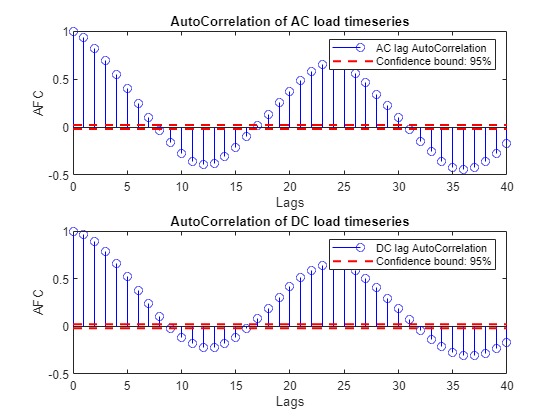


Lags = 40;
confidenceBound = 0.05;

[afcAC ,afcLags, bounds] = autocorr(data.AC(:),NumLags = Lags, NumSTD=1.96);
[afcDC ,afcLags, bounds] = autocorr(data.DC(:),NumLags = Lags, NumSTD=1.96);


figure;
subplot(2,1,1)
stem(afcLags,afcAC, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(afcLags, repmat(bounds(1),length(afcLags )), 'r--' , "LineWidth",1.5);
plot(afcLags, repmat(bounds(2),length(afcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("AC lag AutoCorrelation", "Confidence bound: 95%")
title('AutoCorrelation of AC load timeseries')

subplot(2,1,2)
stem(afcLags,afcDC, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(afcLags, repmat(bounds(1),length(afcLags )), 'r--' , "LineWidth",1.5);
plot(afcLags, repmat(bounds(2),length(afcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("DC lag AutoCorrelation", "Confidence bound: 95%")
title('AutoCorrelation of DC load timeseries')


[h, pValue, statistic, critValue] = kpsstest(data.AC,ALpha = 0.05)

h = logical
   1


pValue = 0.0100

statistic = 4.1607

critValue = 0.1460


[h, pValue, statistic, critValue] = kpsstest(data.DC,ALpha = 0.05)

h = logical
   1


pValue = 0.0100

statistic = 12.4095

critValue = 0.1460

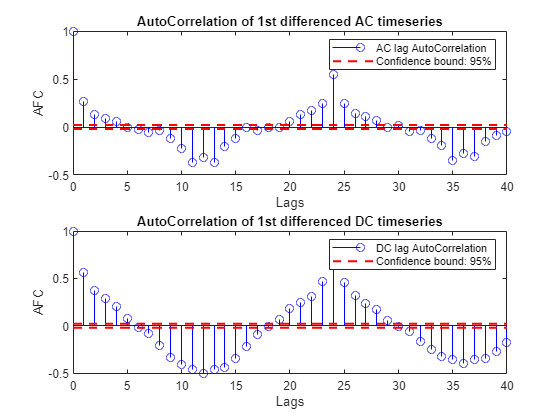



ACdiff = array2table(diff(data.AC), "VariableNames","ACdiff");
DCdiff = array2table(diff(data.DC),"VariableNames", "DCdiff");

data = [data(2:end,:) ACdiff DCdiff];

Lags = 40;
confidenceBound = 0.05;

[afcAC ,afcLags, bounds] = autocorr(data.ACdiff,NumLags = Lags, NumSTD=1.96);
[afcDC ,afcLags, bounds] = autocorr(data.DCdiff,NumLags = Lags, NumSTD=1.96);


figure;
subplot(2,1,1)
stem(afcLags,afcAC, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(afcLags, repmat(bounds(1),length(afcLags )), 'r--' , "LineWidth",1.5);
plot(afcLags, repmat(bounds(2),length(afcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("AC lag AutoCorrelation", "Confidence bound: 95%")
title('AutoCorrelation of 1st differenced AC timeseries')

subplot(2,1,2)
stem(afcLags,afcDC, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(afcLags, repmat(bounds(1),length(afcLags )), 'r--' , "LineWidth",1.5);
plot(afcLags, repmat(bounds(2),length(afcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("DC lag AutoCorrelation", "Confidence bound: 95%")
title(['AutoCorrelation of 1st differenced DC timeseries'])

Looking at the auto correlation of the first differenced series we can see that for the ACdiff sereies there is one clear component over and up to 4 values that are marginally over. 

For the DCdiff series there are more significantly active components with a marginal 5 component. 

if d = 1

q range :  1-4

[h, pValue, statistic, critValue] = kpsstest(data.ACdiff,ALpha = 0.05)

h = logical
   0


pValue = 0.1000

statistic = 0.0011

critValue = 0.1460


[h, pValue, statistic, critValue] = kpsstest(data.DCdiff,ALpha = 0.05)

h = logical
   0


pValue = 0.1000

statistic = 0.0016

critValue = 0.1460

The KPSS test on the first differenced series has returned that the null assumtion has not been rejected (the null assumption is therefore true) The null assumtion is that the series is stationary. 

Therefore we can set d=1; 

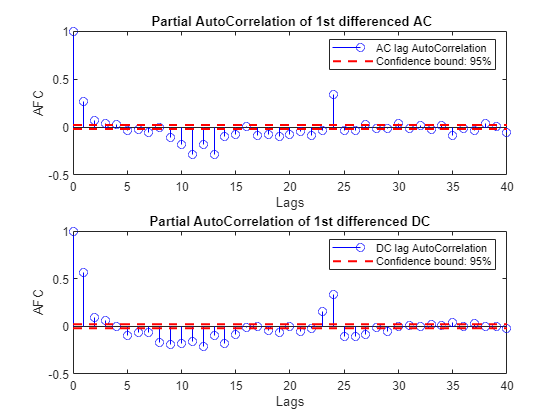



Lags = 40;
confidenceBound = 0.05;

[pafcACdiff ,pafcLags, bounds] = parcorr(data.ACdiff,NumLags = Lags, NumSTD=1.96);
[pafcDCdiff ,pafcLags, bounds] = parcorr(data.DCdiff,NumLags = Lags, NumSTD=1.96);


figure;
subplot(2,1,1)
stem(pafcLags,pafcACdiff, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(pafcLags, repmat(bounds(1),length(pafcLags )), 'r--' , "LineWidth",1.5);
plot(pafcLags, repmat(bounds(2),length(pafcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("AC lag AutoCorrelation", "Confidence bound: 95%")
title(' Partial AutoCorrelation of 1st differenced AC')

subplot(2,1,2)
stem(pafcLags,pafcDCdiff, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(pafcLags, repmat(bounds(1),length(pafcLags )), 'r--' , "LineWidth",1.5);
plot(pafcLags, repmat(bounds(2),length(pafcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("DC lag AutoCorrelation", "Confidence bound: 95%")
title('Partial AutoCorrelation of 1st differenced DC')

The pafc of the 1st differenced series shows one components clearly over the confidence bound and a second and third component that is marginally over, this makes it worth trying some different values. 

expeted p range: 1-3 

Time to build and test the model 

Gonna remove everything except the timeseries

data = removevars(data, ["ACdiff" "DCdiff" "dayTime" "OffPeak" "Peak" "Sat" "Standard" "Sun" "tou_id"  "wrkHr"]);


numObservations = height(data);
percentSplit = 0.7;

idxTrain = 1:floor(percentSplit*numObservations);
idxTest = floor(percentSplit*numObservations)+1:numObservations;
X = data(idxTrain,:);
T = data(idxTest,:);

First model is for AC :

p =2(slightly more to account for slightly under differenced;  d= 1 ; q =2 ; 

Train Model


ARIMA_AC = arima('Constant',NaN,'ARLags',1:3,'D',1,'MALags',1:2 ,'Distribution','Gaussian');
ARIMA_AC = estimate(ARIMA_AC,X.AC,'Display','off');

Test Model

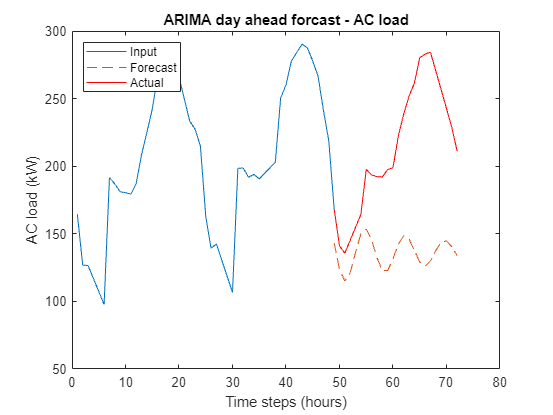

nForecast = 24;

offset = 49;
[Y, Ymse] = forecast(ARIMA_AC, nForecast, T.AC(1:offset) );

xAxis = 1:offset+nForecast-1;
figure
plot(1:offset,T.AC(1:offset))
hold on
plot(offset:offset+nForecast-1, Y,"--")
plot(offset:offset+nForecast-1, T.AC(offset:offset+nForecast-1),"r")
hold off
ylabel("AC load (kW)")
   xlabel("Time steps (hours)")
   title("ARIMA day ahead forcast - AC load")
legend("Input", "Forecast", "Actual", "Location","northwest")

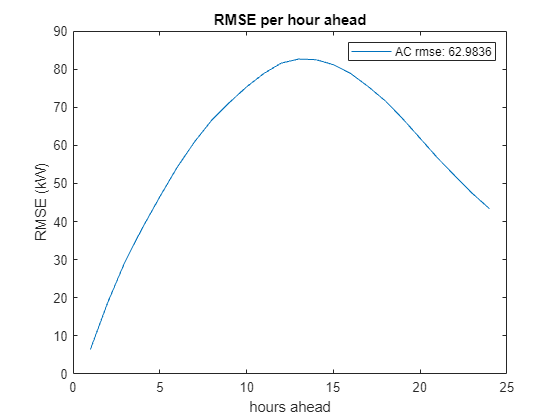




timeStep=1;

for j = 1:(floor(length(T.AC(:))/timeStep)-ceil(24/timeStep)-24)

    offset = 24+j*timeStep;
    [Y, Ymse] = forecast(ARIMA_AC, nForecast, T.AC(1:offset) );

    numTimeSteps = offset+nForecast-1;

    
    rmse(j) = mean((Y - T.AC(offset:numTimeSteps)).^2,"all");
    mape(j) = mean(abs(T.AC(offset:numTimeSteps)-Y)./T.AC(offset:numTimeSteps),"all")*100;
  

    rmsePerHr(j,:) = (Y - T.AC(offset:numTimeSteps)).^2;
    mapePerHr(j,:) =   (abs(T.AC(offset:numTimeSteps)-Y )./T.AC(offset:numTimeSteps)).*100;
end


for i = 1:24
    hourlyACrmse(i) = sqrt(mean(rmsePerHr(:,i),"all"));
    %hourlyDCrmse(i) = sqrt(mean(rmsePerHr(:,3,i),"all"));
    hourlyACmape(i) = mean(mapePerHr(:,i),"all");
    %hourlyDCmape(i) = mean(mapePerHr(:,3,i),"all");
end

figure
plot(1:24, hourlyACrmse);
hold on
%plot(1:24,hourlyDCrmse);
hold off
legend("AC rmse: "+ sqrt(mean(rmse(:))))%, "DC rmse: "+ sqrt(mean(rmse(:,3))))
title("RMSE per hour ahead")
xlabel("hours ahead")
ylabel("RMSE (kW)")

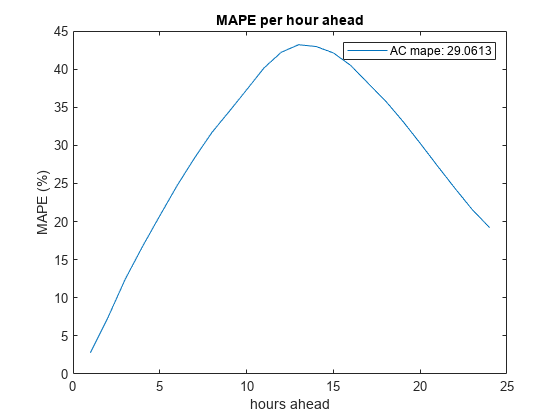

figure
plot(1:24, hourlyACmape);
hold on
%plot(1:24,hourlyDCmape);
hold off
legend("AC mape: " + mean(hourlyACmape))%, "DC mape: "+ mean(hourlyDCmape))
title("MAPE per hour ahead")
xlabel("hours ahead")
ylabel("MAPE (%)")



display("AC MAPE: " + mean(mape(:))+"%")

    "AC MAPE: 29.0613%"



display("AC RMSE: " + sqrt(mean(rmse(:)))+" kW")

    "AC RMSE: 62.9836 kW"



%display("DC MAPE: " + mean(mape(:,3))+"%")
%display("DC RMSE: " + sqrt(mean(rmse(:,3)))+" kW")


Sesonality vibe, maybe try 24? 

data= dataClean

data = 8760×12 table
           tstamp             AC      tou_id     DC      weekDay    Sat    Sun    wrkHr    dayTime    OffPeak    Peak    Standard
    ____________________    ______    ______    _____    _______    ___    ___    _____    _______    _______    ____    ________

    01-Jan-2022 00:00:00    96.855      3         230       0        1      0       0         0          1        0         0    
    01-Jan-2022 01:00:00    97.053      3       229.2       0        1      0       0         0          1        0         0    
    01-Jan-2022 02:00:00    97.229      3       22

data= dataClean

data = 8760×12 table
           tstamp             AC      tou_id     DC      weekDay    Sat    Sun    wrkHr    dayTime    OffPeak    Peak    Standard
    ____________________    ______    ______    _____    _______    ___    ___    _____    _______    _______    ____    ________

    01-Jan-2022 00:00:00    96.855      3         230       0        1      0       0         0          1        0         0    
    01-Jan-2022 01:00:00    97.053      3       229.2       0        1      0       0         0          1        0         0    
    01-Jan-2022 02:00:00    97.229      3       22

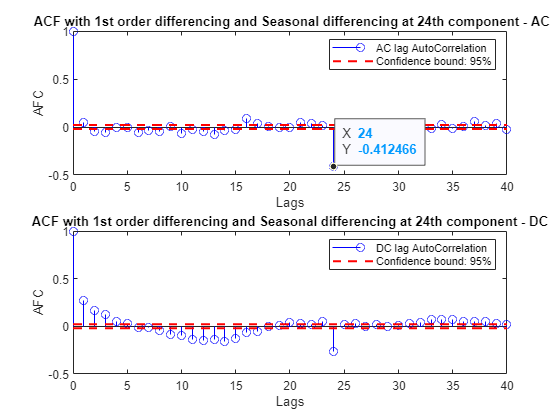





%First order differencing
ACdiff = array2table(diff(data.AC), "VariableNames","ACdiff");
DCdiff = array2table(diff(data.DC), "VariableNames","DCdiff");
data = [data(2:end,:) ACdiff DCdiff];


DC2diff = array2table(diff(data.DCdiff), "VariableNames","DC2diff");
data = [data(2:end,:) DC2diff];

slag = 24; %seasonal lag component
%Seasonal differencing
ACsdiffdiff = data.ACdiff(slag+1:end) - data.ACdiff(1:end-slag); 
ACsdiffdiff = array2table(ACsdiffdiff, "VariableNames","ACsdiffdiff");
DCsdiffdiff = data.DCdiff(slag+1:end) - data.DCdiff(1:end-slag);
DCsdiffdiff = array2table(DCsdiffdiff, "VariableNames","DCsdiffdiff");
data = [data(25:end,:) ACsdiffdiff DCsdiffdiff];



Lags = 40;
confidenceBound = 0.05;


[afcACsdiffdiff ,afcLags, bounds] = autocorr(data.ACsdiffdiff,NumLags = Lags, NumSTD=1.96);
figure;
subplot(2,1,1)
stem(afcLags,afcACsdiffdiff, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(afcLags, repmat(bounds(1),length(afcLags )), 'r--' , "LineWidth",1.5);
plot(afcLags, repmat(bounds(2),length(afcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("AC lag AutoCorrelation", "Confidence bound: 95%")
title(' ACF with 1st order differencing and Seasonal differencing at 24th component - AC')


[afcDCsdiffdiff ,afcLags, bounds] = autocorr(data.DCsdiffdiff,NumLags = Lags, NumSTD=1.96);
subplot(2,1,2)
stem(afcLags,afcDCsdiffdiff, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(afcLags, repmat(bounds(1),length(afcLags )), 'r--' , "LineWidth",1.5);
plot(afcLags, repmat(bounds(2),length(afcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("DC lag AutoCorrelation", "Confidence bound: 95%")
title('ACF with 1st order differencing and Seasonal differencing at 24th component - DC')

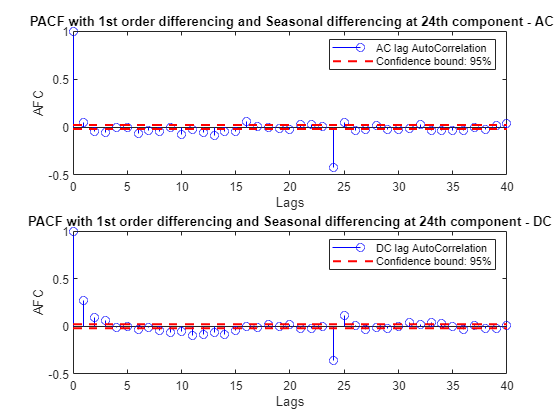



Lags = 40;
confidenceBound = 0.05;


[pafcACsdiffdiff ,afcLags, bounds] = parcorr(data.ACsdiffdiff,NumLags = Lags, NumSTD=1.96);
figure;
subplot(2,1,1)
stem(afcLags,pafcACsdiffdiff, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(afcLags, repmat(bounds(1),length(afcLags )), 'r--' , "LineWidth",1.5);
plot(afcLags, repmat(bounds(2),length(afcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("AC lag AutoCorrelation", "Confidence bound: 95%")
title(' PACF with 1st order differencing and Seasonal differencing at 24th component - AC')


[pafcDCsdiffdiff ,afcLags, bounds] = parcorr(data.DCsdiffdiff,NumLags = Lags, NumSTD=1.96);
subplot(2,1,2)
stem(afcLags,pafcDCsdiffdiff, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(afcLags, repmat(bounds(1),length(afcLags )), 'r--' , "LineWidth",1.5);
plot(afcLags, repmat(bounds(2),length(afcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("DC lag AutoCorrelation", "Confidence bound: 95%")
title('PACF with 1st order differencing and Seasonal differencing at 24th component - DC')




%21%MAPE
%SARIMA_AC = arima('Constant',NaN,'ARLags',1:2,'D',1,'MALags',1,'SARLags',24,'Seasonality',24,'SMALags',24,'Distribution','Gaussian');
%SARIMA_AC = estimate(SARIMA_AC,X.AC,'Display','off');

%20%MAPE
%SARIMA_AC = arima('Constant',NaN,'ARLags',1:2,'D',1,'MALags',1,'SARLags',24,'Seasonality',0,'SMALags',24,'Distribution','Gaussian');
%SARIMA_AC = estimate(SARIMA_AC,X.AC,'Display','off');

SARIMA_AC = arima('Constant',NaN,'D',1,'Seasonality',24,'SMALags',24,'Distribution','Gaussian');
SARIMA_AC = estimate(SARIMA_AC,X.AC,'Display','off');


%21.7%
% AC = X.AC;
% weekDay = X.weekDay;
% weekendDay = X.weekendDay;
% 
% %% Seasonal ARIMA Model Using Exogenous Predictors
% % Estimate a SARIMAX Model of AC
% SARIMAX_AC = arima('Constant',0,'ARLags',1:2,'D',1,'MALags',1,'SARLags',24,'Seasonality',0,'SMALags',24,'Distribution','Gaussian');
% validIndices = find(~any(isnan([AC,weekDay,weekendDay]),2));
% preSampleNumber = SARIMAX_AC.P;
% preSampleResponse = AC(validIndices(1:preSampleNumber));
% estimateResponse = AC(validIndices(preSampleNumber+1:end));
% SARIMA_AC = estimate(SARIMAX_AC,estimateResponse,'Y0',preSampleResponse,'X',[weekDay,weekendDay],'Display','off');

Test Model

nForecast = 24;

offset = 300;
[Y, Ymse] = forecast(SARIMA_AC, nForecast,T.AC(1:offset) ); %,'X0',[T.weekDay(1:offset) T.weekendDay(1:offset)] 

xAxis = 1:offset+nForecast-1;
figure
plot(1:offset,T.AC(1:offset))
hold on
plot(offset:offset+nForecast-1, Y,"r--")
plot(offset:offset+nForecast-1, T.AC(offset:offset+nForecast-1))
hold off
legend("Input", "Forecast", "Actual")

timeStep=1;

for j = 1:(floor(length(T.AC(:))/timeStep)-ceil(24/timeStep)-72)

    offset = 72+j*timeStep;
    [Y, Ymse] = forecast(SARIMA_AC, nForecast, T.AC(1:offset-1) );

    numTimeSteps = offset+nForecast-1;

    Ypred{j}(:) = Y;
    Yactual{j}(:) = T.AC(offset:numTimeSteps);
    Xactual{j}(:) = T.AC(offset-24:offset-1);
    YpredMse{j}(:) =Ymse;

    rmse(j) = mean((Y - T.AC(offset:numTimeSteps)).^2,"all");
    mape(j) = mean(abs(T.AC(offset:numTimeSteps)-Y)./T.AC(offset:numTimeSteps),"all")*100;
  
    mse(j,:)  = Ymse;
    rmsePerHr(j,:) = (Y - T.AC(offset:numTimeSteps)).^2;
    mapePerHr(j,:) =   (abs(T.AC(offset:numTimeSteps)-Y )./T.AC(offset:numTimeSteps)).*100;
end

YmapeHr = zeros(24,1);
Yrmse   = zeros(24,1);
YseCal = zeros(24,1);
for i=1:j
Ymape{i}(:) = abs(Yactual{i} - Ypred{i})./(Yactual{i})*100;
YmapeHr(:) = YmapeHr + Ymape{i}(:);

Yrmse(:) =  Yrmse(:)+YpredMse{i}(:);

YseCal(:) = YseCal(:) + (Yactual{i}(:) - Ypred{i}(:)).^2;
end

YmapeHr = YmapeHr./j;
Yrmse   = sqrt(Yrmse./j);
YrmseCal = sqrt(YseCal./j);



for i = 1:24
    hourlyACrmse(i) = sqrt(mean(rmsePerHr(:,i),"all"));
    %hourlyDCrmse(i) = sqrt(mean(rmsePerHr(:,3,i),"all"));
    hourlyACmape(i) = mean(mapePerHr(:,i),"all");
    %hourlyDCmape(i) = mean(mapePerHr(:,3,i),"all");
    givenRMSE(i)  = sqrt(mean(mse(:,i),'all'));
end

figure
plot(1:24, hourlyACrmse);
hold on
%plot(1:24,hourlyDCrmse);
plot(givenRMSE,"DisplayName","Given RMSE");
plot(Yrmse)
plot(YrmseCal)
hold off
legend("AC rmse: "+ sqrt(mean(rmse(:))), "In loop Given", "out of loop Given" ,"out of loop Cal")%, "DC rmse: "+ sqrt(mean(rmse(:,3))))
title("RMSE per hour ahead")
xlabel("hours ahead")
ylabel("RMSE (kW)")
figure
plot(1:24, hourlyACmape);
hold on
plot(YmapeHr)
%plot(1:24,hourlyDCmape);
hold off
legend("AC mape: " + mean(hourlyACmape), "alt MAPE" + mean(YmapeHr))%, "DC mape: "+ mean(hourlyDCmape))
title("MAPE per hour ahead")
xlabel("hours ahead")
ylabel("MAPE (%)")


display("AC MAPE: " + mean(mape(:))+"%")
display("AC RMSE: " + sqrt(mean(rmse(:)))+" kW")
%display("DC MAPE: " + mean(mape(:,3))+"%")
%display("DC RMSE: " + sqrt(mean(rmse(:,3)))+" kW")
